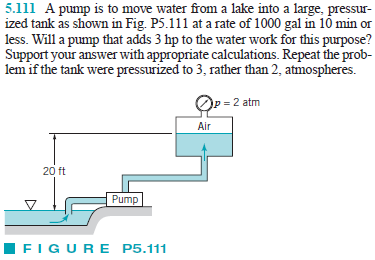

# given

u = symunit;
Wdotshaft = 3*u.HP_UK;
dVol = 1000*u.gal;
dt = 10*u.min;
gamma = 62.4*u.lbf/u.ft^3;
g = 32.2*u.ft/u.s^2;

# inflow properties

p1 = 0;
V1 = 0;
z1 = 0;

# outflow properties

p2 = [2 3]*u.atm;
V2 = 0;
z2 = 20*u.ft;

# conservation of energy

hL = sym('hL', [1 2]);
Q = rewrite(dVol/dt, 'US');
hs = rewrite(Wdotshaft/(gamma*Q), 'US');
hL = solve(p2/gamma+V2^2/(2*g)+z2 == p1/gamma+V1^2/(2*g)+z1+hs-hL);
hL = simplify(sym(struct2cell(hL))).';
hL_vpa = vpa(hL, 4) %#ok

$$hL\_vpa = \left(\begin{array}{cc} 30.85\,\mathrm{ft} & -3.06\,\mathrm{ft} \end{array}\right)$$

clear hL_vpa;